# Team doubleE - Task 1 Report

**Team Members: Andrew Wunderlich, Jay Desai, Miles Leonard-Albert **

***CSCE585 - Machine Learning Systems***

***Fall 2020 Adversarial ML Project***

This report was created in MATLAB as a live script (.mlx file) and exported to a PDF.

clear variables %reset workspace
close all; %close plots from previous runs

## Task Background

This report provides insight and analysis into Task 1, in which we create adversarial examples using the Athena framework and test the adversarial examples against several defenses to compare performance.  

Adversarial machine learning is currently a hot research topic within the AI/ML research community.  The idea behind adverasrial ML is that machine learning classifiers and decision makers can be tricked into misclassifying important examples or making bad decisions.  There are many potential ways to attack ML systems, but in this case we consider that the attack happens by an attacker slightly modifying the input data.  Such attacks can be very subtle--sometimes even imperceptible to the human eye--but can nonetheless be very sucessful in fooling a well-trained ML model.

To make critical ML systems more robust against attacks like these, several ML defenses have been proposed.  No defense is perfect, but a good defense will significantly lower the error rate created by a wide variety of adversarial examples and increase the computational cost of generating attacks even when the full defense mechanism is known and accounted for by the attacker.  This project explores a recently propopsed defense called Athena, which is essentially a framework for creating an ensemble of very simple "weak defenses" [1].  Each weak defense performs a basic transformation on the input example image and performs a classification using a separate neural network which is trained on the transformed images. By itself, a single weak defense is not always useful, but with many weak defenses in an ensemble, Athena can be resilient to strong attacks.

In this task, we create several ensemble defenses using the Athena framework and test the defenses against several zero-knowledge attacks.  The zero-knowledge attack model assumes that the attacker does not know any details about the defense in place, and can only generate attacks based on an undefended classifier.  We also test the same zero-knowledge attacks against the undefended model and against a baseline "strong" defense (PGD-ADT) for comparison with the ensemble defenses.

## Import Project Data and Analyze Composition

All data from the Task 1 assignment was dumped into a single file [\data\predictionData.mat] which contains the following variables:

- labels: an array of the correct values associated with each training example

- predictionData: a 3-dimensional array of predicted digits, in which each row (1st dim) corresponds to an image in the test set, each column (2nd dim) corresponds to a tested attack, each layer (3rd dim) corresponds to tested defense.

### Load labels and raw prediction data

projectdir = 'C:\Users\andre\CSCE585_local\project-athena'

predictionData = struct with fields:
    predictions: [1000×15×4 int32]
         labels: [1×1000 int64]
     pred_bs_um: [1×1000 int64]


%first run data, with 3 WDs in Athena
predictionData = load([projectdir,'\data\predictionData.mat']) 


predictionData2 = struct with fields:
    predictions: [1000×15×4 int32]
         labels: [1×1000 int64]
     pred_bs_um: [1×1000 int64]


%second run data, with 20 WDs in Athena
predictionData2 = load([projectdir,'\data\predictionData2.mat'])  

labels = predictionData.labels;
pred_bs_um = predictionData.pred_bs_um;
predictions = predictionData.predictions;

%add layers for AVEP-20 and MV-20
predictions(:,:,5:6) = predictionData2.predictions(:,:,2:3);  


num_images = size(predictions,1);   % rows
num_attacks = size(predictions,2);  % columns
num_defenses = size(predictions,3); % layers

if(length(labels) ~= num_images) 
    error('Number of labels not equal to number of images. Please check dimensions.')
end

### Analyze Composition by Labels

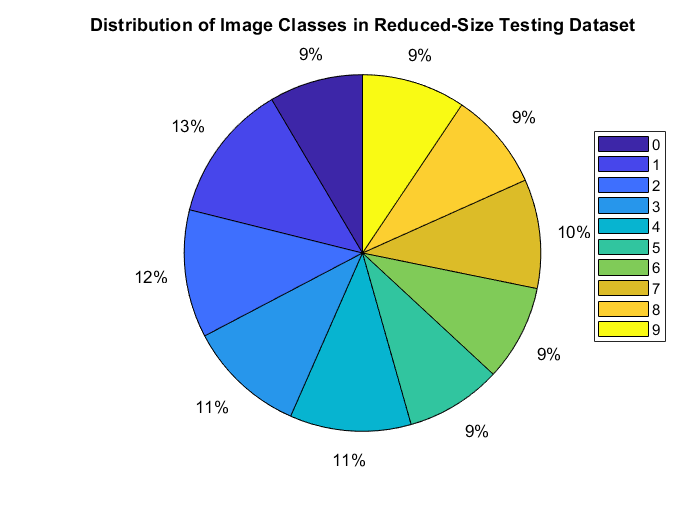

digits = unique(labels);
digitCounts = zeros(size(digits));
for i = 1:length(labels)
    for j = 1:length(digits)
        if(labels(i) == digits(j))
            digitCounts(j) = digitCounts(j) + 1;
            break;
        end
    end
end
pie(digitCounts);  title('Distribution of Image Classes in Reduced-Size Testing Dataset');

legend(string(digits), 'Position', [0.85 0.45 0.1 0.2]);

## Details About Attacks

This task includes 15 attacks, featuring 3 attack types, each at 5 different intensities.  Below we plot a few examples of images from the MNIST dataset modified using the following attacks:

### Spatial transformation

#### Background

Rather than adjusting pixel values (which has the effect of adding "noise" to the picture, the spatial transformation attack seeks to distort the image by slightly relocating pixels within the image [2].  In particular, the spatially transformed attack uses differentiable bilinear interpolation to transform the input image with the flow field. The resulting adversarial examples are calculated as:


$$x_{\mathrm{adv}}^{\left(i\right)} =\sum_{q\subset N\left(u^{\left(i\right)} ,v^{\left(i\right)} \right)} {\mathit{\mathbf{x}}}^{\left(q\right)} \left(1-|u^{\left(i\right)} -u^{\left(q\right)} |\right)\left(1-|v^{\left(i\right)} -v^{\left(q\right)} |\right)\;\;$$


Here $N\;\left(u^{\left(i\right)} ,v^{\left(i\right)} \right)$ are the indices of the 4-pixel neighbors at the location $\left(u^{\left(i\right)} ,v^{\left(i\right)} \right)$. 

#### Experimental Details

We tested five spatial transformation attack variants w/ max rotation:

- 10 degrees

- 20 degrees

- 30 degrees

- 40 degrees

- 50 degrees

The spatial transormation attack can, shift, distort, and rotate the image.  In this case, the attack was configured to use minimal shift but to induce significant rotation:

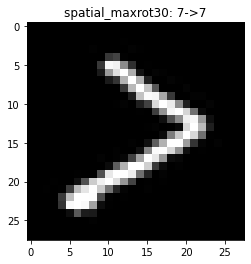

### PGD

#### Background

Projected gradient descent (PGD) is a powerful adversarial attack that is a multi-step version of the single-step fast gradient sign method (FGSM). A few years after FGSM was proposed in [3], PGD was proposed by Aleksander Madry and four colleagues from MIT in 2018 [4]. PGD adds noise to the image by iterating the following calculation:


$$x_{t+1} =\Pi {\;}_{x+S} \left(x_t +\epsilon \;\mathrm{sign}\left(\nabla_x J\left(\Theta ,\mathit{\mathbf{x}},y\right)\right)\right)\;$$


Here $\epsilon \;$is the strength of the attack, $\mathit{\mathbf{x}}$ is the model input, $y$ is the target associated with $\mathit{\mathbf{x}}$, $\Theta$ is the model parameters, and $J$ is the cost function used to train the network.

The multistep nature of PGD makes it more computationally expensive than the single-step FGSM method, but it generally should produce better and more optimal attacks than FGSM, perhaps especially for high attack intensity where the nonlinearity of the neural network plays a more significant role.

#### Experimental Details

We used five PGD variants with epsilon:

- 0.03

- 0.07

- 0.10

- 0.20

- 0.30

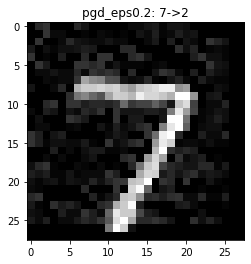

### BIM 

#### Background

The basic iterative method (BIM) is another iterative extension of the FGSM attack [5].  Essentially, BIM applies the FGSM attack multiple times using a small step size, and clips pixel values of intermediate results after each step to ensure that the max norm of the attack remains bounded by teh attack strength $\epsilon$. Using BIM, adversarial examples are generated by initializing $x_0^{\mathrm{adv}} =x$ and then iterating the following calculation


$$x_{N+1}^{\mathrm{adv}} ={\mathrm{Clip}}_{X,\epsilon } \left\lbrace x_N^{\mathrm{adv}} +\alpha \;\mathrm{sign}\left(\nabla_{x\;} J\left(x_N^{\mathrm{adv}} ,y_{\mathrm{true}} \right)\right)\right\rbrace$$


The parameter $\alpha$ can be altered as well, but the original authors of [5] suggest using $\alpha =1$. 

#### Experimental Details

We used five BIM attack variants with epsilon:

- 0.1

- 0.2

- 0.3

- 0.4

- 0.5

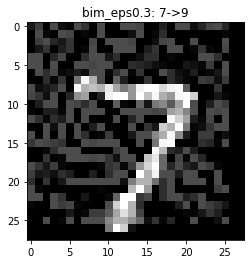

## Details about Defenses

This work uses the following defense models:

- UM: The undefended model (a single CNN with no special defenses)

- AVEP-3: "Vanilla Athena" with the Average Probability ensemble strategy, using 3 weak defenses

- MV-3: "Vanilla Athena" with the Majority Voting ensemble strategy, using 3 weak defenses

- PGD-ADT: PGD Adversarial Training, a state-of-the-art Adversarial Defense

- AVEP-20: "Vanilla Athena" with the Average Probability ensemble strategy, using 20 weak defenses

- MV-20: "Vanilla Athena" with the Majority Voting ensemble strategy, using 20 weak defenses

In the ensemble methods, the weak defenses were chosen somewhat arbitrarily, but we made sure to choose a diverse set of weak defenses, especially in the case of the 20-WD ensembles.

## Analyzing Error Rates

For each defense, we ran 15,000 perturbed images (15 attack variants * 1,000 of the 10,000 test images in MNIST) and obtained predictions for each.  We stored the 1,000 correct values (labels) and stored the 15,000 predicted values for each adversarial example vs each defense in a 3D array, from which we can calculate error rates and plot relevant variables.

### Calculate Error Rates

errortable = -ones(size(predictions));

Unrecognized function or variable 'predictions'.

all_err_rates = -ones(num_attacks, num_defenses);

for i = 1:num_attacks
    for j = 1:num_defenses
        
        %To be error, the prediction must not match the label, and the
        %label must have been correctly identified by the undefended model
        %before the attack (i.e. against the benign samples)
        errortable(:,i,j) = ((predictions(:,i,j) ~= labels') & (labels' == pred_bs_um')); 
        
        %The error rate is simply the average of error values across the row
        all_err_rates(i,j) = mean(errortable(:,i,j));
    end
end

### Plot Error Rates by Attack for Each Defense

attacks = {'BIM 0.1' 'BIM 0.2' 'BIM 0.3' 'BIM 0.4' 'BIM 0.5'...
            'PGD 0.03' 'PGD 0.07' 'PGD 0.10' 'PGD 0.20' 'PGD 0.30'...
            'SpaXfm 10' 'SpaXfm 20' 'SpaXfm 30' 'SpaXfm 40' 'SpaXfm 50'};        

#### For Undefended Model:

bar(categorical(attacks), all_err_rates(:,1)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs Undefended Model');

#### For AVEP-3 Ensemble Defense:

bar(categorical(attacks), all_err_rates(:,2)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs AVEP-3 Ensemble Model');

#### For MV-3 Ensemble Defense:

bar(categorical(attacks), all_err_rates(:,3)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs MV-3 Model');

#### For PGD-ADT Defense:

bar(categorical(attacks), all_err_rates(:,4)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs PGD-ADT Model');

#### For AVEP-20 Ensemble Defense:

bar(categorical(attacks), all_err_rates(:,5)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs AVEP-20 Ensemble Model');

#### For MV-20 Ensemble Defense:

bar(categorical(attacks), all_err_rates(:,6)*100); ylabel('Error Rate [%]');  
title('Error Rates for Each Attack vs MV-20 Model');

### Plot Error Rates by Defense for Each Attack

defenses = {'Undefended' 'AVEP-3' 'MV-3' 'PGD-ADT' 'AVEP-20', 'MV-20'};

#### For BIM attack:

figure; 
s1 = subplot(1,5,1);
bar(categorical(defenses), all_err_rates(1,:)*100); 
ylabel('Error Rate [%] vs BIM Attack');  
title('\epsilon = 0.1');
s2 = subplot(1,5,2);
bar(categorical(defenses), all_err_rates(2,:)*100); 
title('\epsilon = 0.2');
s3 = subplot(1,5,3);
bar(categorical(defenses), all_err_rates(3,:)*100);
title('\epsilon = 0.3');
s4 = subplot(1,5,4);
bar(categorical(defenses), all_err_rates(4,:)*100);
title('\epsilon = 0.4');
s5 = subplot(1,5,5);
bar(categorical(defenses), all_err_rates(5,:)*100);
title('\epsilon = 0.5');
linkaxes([s1, s2, s3, s4 ,s5],'y'); %force identical y-scaling on each subplot

For the BIM attack, all defenses fair siginificantly better than the undefended model.  The 20-weak-defense ensembles are comparable to PGD-ADT, while the 3-weak-defense ensembles quickly suffer as the attack strength increases.

#### For PGD attack:

figure; 
s1 = subplot(1,5,1);
bar(categorical(defenses), all_err_rates(6,:)*100); 
ylabel('Error Rate [%] vs PGD Attack');  
title('\epsilon = 0.03');
s2 = subplot(1,5,2);
bar(categorical(defenses), all_err_rates(7,:)*100); 
title('\epsilon = 0.07');
s3 = subplot(1,5,3);
bar(categorical(defenses), all_err_rates(8,:)*100); 
title('\epsilon = 0.10');
s4 = subplot(1,5,4);
bar(categorical(defenses), all_err_rates(9,:)*100);
title('\epsilon = 0.20');
s5 = subplot(1,5,5);
bar(categorical(defenses), all_err_rates(10,:)*100);   
title('\epsilon = 0.30');
linkaxes([s1, s2, s3, s4 ,s5],'y'); %force identical y-scaling on each subplot

For the PGD attack, the defended models outperform the undefended model at all attacks with epsilon > 0.07.  The difference is most pronounced around the range $0\ldotp 1<\epsilon <0\ldotp 2$, where the undefended model misclassifies more than two thirds of the attacked images, but the defended models all still classify them with >90% accuracy.

The PGD-ADT strong defense outperforms the 3-weak-defense ensemble methods at higher attack strengths in this case, but performs very similarly to the 20-weak-defense ensembles.

Interestingly, the 20-weak-defense ensemble defenses perform poorly for the weakest attack case, with error rates of >10% for epsilon = 0.03.  This is very unexpected, as they perform far better (<1% error) when epsilon is increased to 0.07.

#### Spatial Transformation attack:

figure; 
s1 = subplot(1,5,1);
bar(categorical(defenses), all_err_rates(11,:)*100); 
ylabel('Error Rate [%] vs Spatial Transformation Attack');  
title('10 deg');
s2 = subplot(1,5,2);
bar(categorical(defenses), all_err_rates(12,:)*100); 
title('20 Deg');
s3 = subplot(1,5,3);
bar(categorical(defenses), all_err_rates(13,:)*100); 
title('30 Deg');
s4 = subplot(1,5,4);
bar(categorical(defenses), all_err_rates(14,:)*100);   
title('40 Deg');
s5 = subplot(1,5,5);
bar(categorical(defenses), all_err_rates(15,:)*100);   
title('50 Deg');
linkaxes([s1, s2, s3, s4 ,s5],'y'); %force identical y-scaling on each subplot

Interestingly, all defenses do very little to protect against spatial transformation attacks, with the undefended model frequently performing as well or better than the defended models. Also, for low values of rotation (<20 degrees), the 20-weak-defense ensembles perform extremely poorly (far worse than the undefended model!) misclassifying over half of the examples.  The reason for this is unclear.  We may consider choosing different weak defenses for the ensembles and explore if performance improves based on the weak-defense selection.  

For low intensity sptial transformation attacks, low error rates are expected due to the spatial invariance properties of convolutional neural networks.  With higher values of rotation, the models perform worse, with each model misclassifying at least half of the test examples for 50 degree rotation.  We note here that it is impossible for any classifier to perform well for arbitrarily high values of rotation, considering that the picture orientation is one of the ways that the digit is properly discerned.  Indeed, a rotated '6' is indistinguishable from a '9', even for human beings.  We should also note that rotation by more than 30 degrees is visibly apparent, so rotational attacks of that strength would be clearly evident, not subtle. 

## A Note about Team Member Contributions

The difficulties in installing packages and dependencies made it impossible to have a deeply collaborative effort on Task 1, as Miles and Jay were unable to resolve dependencies until after Andrew had already made significant progress towards a solution.  Additionally, being new to GitHub and other tools which are needed to properly collaborate on a common code repository, Andrew was also comfortable taking responsibility for many of the tasks by himself to avoid problems with collaboration generating additional conflicts and new errors.  

Despite this, all team members communicated and demonstrated willingness to help out, and we plan to have a more collaborative team solution for upcoming project tasks.

## References

[1]    Y. Meng, J. Su, J. O'Kane, and P. Jamshidi. "A Framework based on Diverse Weak Defenses for Building Adversarial Defense." [https://arxiv.org/pdf/2001.00308.pdf](https://arxiv.org/pdf/2001.00308.pdf) 

[2]    C. Xiao, J. Zhu, B. Li, W. He, M. Liu, and D. Song. "Spatially Transformed Adversarial Examples." [1801.02612.pdf (arxiv.org)](https://arxiv.org/pdf/1801.02612.pdf)

[3]    I. Goodfellow, J. Schlens, and C. Szegedy. "Explaining and Harnessing Adversarial Examples."  International Converence on Learning Representations (ICLR), 2015. San Diego, CA, USA. [1412.6572.pdf (arxiv.org)](https://arxiv.org/pdf/1412.6572.pdf).

[4]    A. Madry, A. Makelov, L. Schmidt, D. Tsipras, and A. Vladu.  "Towards Deep Learning Models Resistant to Adversarial Attacks." International Converence on Learning Representations (ICLR), 2018. Vancouver, Canada.[1706.06083.pdf (arxiv.org)](https://arxiv.org/pdf/1706.06083.pdf).

[5]    A. Kurakin, I. Goodfellow, S. Bengio.  "Adversarial examples in the physical world." International Conference on Learning Representations (ICLR) 2017. Toulon, France. [1607.02533.pdf (arxiv.org)](https://arxiv.org/pdf/1607.02533.pdf)